## EEL839 - Transmissão Digital

## Parte 1 - Geração de dados para auxiliar no treinamento da rede neural

Trabalho sobre o artigo: Adversarial training based channel estimation to mitigate jamming attacks in OFDM systems

Guilherme Araujo Thomaz

Este código implementa a parte do trabalho referente às simulações no Matlab para geração dos dados utilizados para treinar a rede neural.

## 1 - Estimação de canal OFDM por LS

### Parâmetros para plotagem

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

### Parâmetros para simulação

N = 1024;           % Número de subportadoras (símbolos por bloco)
ts = 200e-9;        % Tempo de um símbolo
fs = 1/ts;          % Taxa de amostragem
fc = 2e9;           % Frequência da portadora
v = 4/3.6;          % Velocidade em m/s
L = 9;              % Ordem do canal
B = 4;              % Bits por símbolo
Q = 2^B;            % Tamanho da constelação
N_blocks = 1;       % Número de blocos transmitidos
N_FFT = 1024;
SNR = 30;           % Decibeis
K = 5;              % Redundância
S = N+K;            % Tamanho total do bloco (amostras + redundância)

### Geração do canal

% Créditos para a pesquisa de Miranda, L. D. S. G. (2021). 
% ESTIMADOR DE CANAIS EM SISTEMA OFDM UTILIZANDO APRENDIZADO DE MAQUINA 
% (Doctoral dissertation, Universidade Federal do Rio de Janeiro).
% O trabalho me ajudou a implementar esta parte.
c = physconst('LightSpeed'); % Velocidade da luz no espaço livre
max_doppler_shift = v*fc/c;

% Teste com canal diferente, mais fácil de lidar
%max_doppler_shift = 1;
chan = stdchan('cdmaTUx',fs,max_doppler_shift); % Gera canal

### Testando canal pela resposta ao impulso

%chan.Visualization = 'Frequency response';
%chan.Visualization = 'Impulse and frequency responses';
%channel.SamplesToDisplay = '100%';
%y = chan(0);

data = zeros(100,1); % Esse 100 poderia ser qualquer coisa
data(1) = 1; % Gera impulso
h_coef = chan(data);
h_coef = h_coef(7:L+7);
h_coef = normalize_signal(h_coef);

### Fixando canal de teste

h_coef = [
    0.6116 + 0.0538i;
   -0.3152 - 0.0319i;
   -0.3045 + 0.1517i;
   -0.4365 + 0.2198i;
   -0.1024 - 0.3100i;
   -0.1597 - 0.1125i;
    0.0210 + 0.2288i;
    0.1516 - 0.0144i;
   -0.1085 - 0.1425i;
   -0.0022 + 0.0865i;
];
%h_coef = zeros(10,1); h_coef(1)=1; % Teste com canal plano
h_coef = normalize_signal(h_coef);

### Plotando a resposta ao impulso do canal (no tempo)

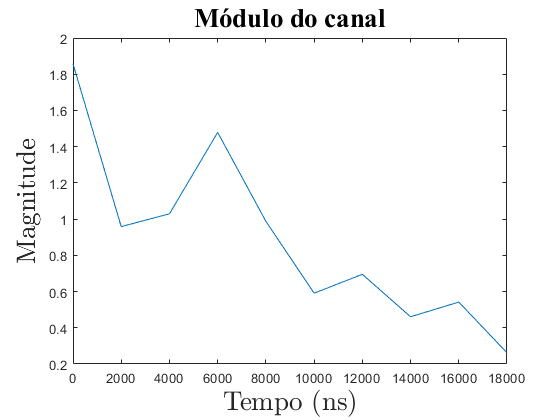

t = (0:ts:(L*ts))*10e9;
%plot(t,real(h_coef));
%title('Parte real do canal','fontname',fontname,'fontsize',fontsize);
%xlabel('Tempo (ns)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%plot(t,imag(h_coef));
%title('Parte imaginária do canal','fontname',fontname,'fontsize',fontsize);
%xlabel('Tempo (ns)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
plot(t,abs(h_coef));
title('Módulo do canal','fontname',fontname,'fontsize',fontsize);
xlabel('Tempo (ns)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

### Resposta em frequência do canal

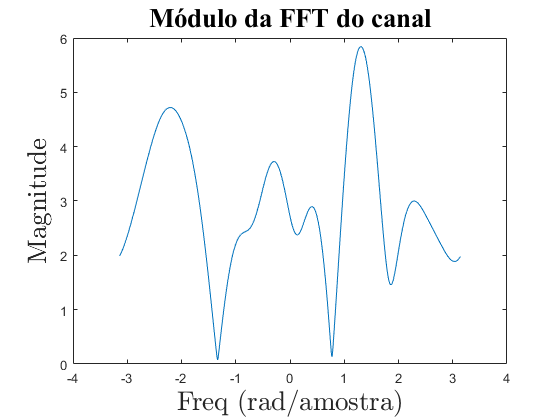

h_fft = fft(h_coef,N_FFT);
freq = 2*pi*linspace(-0.5,0.5,N_FFT);
plot(freq, abs(h_fft));
title('Módulo da FFT do canal','fontname',fontname,'fontsize',fontsize);
xlabel('Freq (rad/amostra)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

### Transmissão OFDM

pilot_symbols = (rand(1,N)+1i*rand(1,N))';  % Símbolos combinados para estimação de canal
x = sqrt(N)*ifft(pilot_symbols);                 

A_cp = [zeros(K,N-K) eye(K); eye(N)];       % Matriz de adição de prefixo cíclico
up = A_cp*x;

### Propagação do sinal no canal

h_coef_noisy = add_noise(h_coef,SNR);          % Ruído nas amostras do canal (não usado agora)                  
z = fftfilt(h_coef_noisy, up);                 % Passa pelo canal
z = add_noise(z,inf);                          % Ruído no sinal  

### Recepção OFDM

R_cp = [zeros(N,K) eye(N)];                 % Matriz de remoção de prefixo cíclico
y = R_cp*z;

retrieved_symbols = fft(y)/sqrt(N);

### Estimação do canal por LS

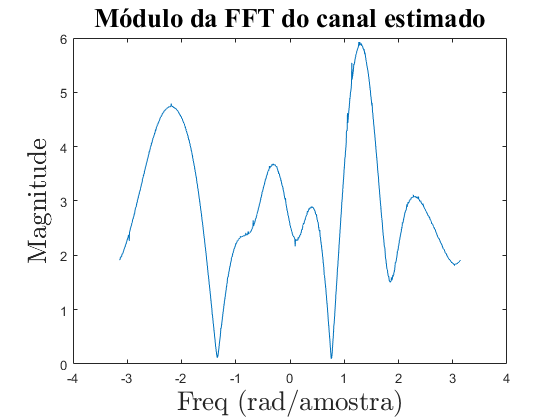

h_LS = retrieved_symbols./pilot_symbols;
plot(freq, abs(h_LS));
title('Módulo da FFT do canal estimado','fontname',fontname,'fontsize',fontsize);
xlabel('Freq (rad/amostra)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

### Qualidade da estimação, pela MSE (quanto menor melhor)

immse(h_LS,h_fft)

ans = 0.0102

%immse(h_LS,fft(h_coef_noisy,N_FFT))

## 2 - Ataque aleatório

ap = add_noise_from_power(zeros(length(up),1),0.01);
z = fftfilt(h_coef_noisy, up) + ap;               
y = R_cp*z;
retrieved_symbols = fft(y)/sqrt(N);
h_LS = retrieved_symbols./pilot_symbols;
immse(h_LS,h_fft)

ans = 0.0687

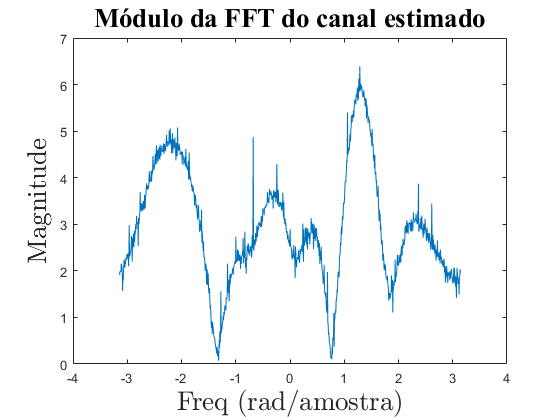

plot(freq, abs(h_LS));
title('Módulo da FFT do canal estimado','fontname',fontname,'fontsize',fontsize);
xlabel('Freq (rad/amostra)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

## 3 - Geração de dados para a rede neural (e média de erro)

N_samples = 3000;
H = [];
errors = [];

for sample_index = 1:N_samples
    [h_coef,h_coef_noisy,h_FFT,h_FFT_noisy]= generate_random_channel(SNR,v,fc,L,fs,N_FFT);
    
    [up,pilot_symbols] = generate_transmitter_signal(N,K);                    
    
    z = fftfilt(h_coef_noisy, up);  
    z = add_noise(z,inf);
    
    retrieved_symbols = generate_received_signal(z,N,K);
    
    h_LS = retrieved_symbols./pilot_symbols;
    
    error = immse(h_LS,h_FFT);
    errors = horzcat(errors,error);
    
    h_FFT_noisy_real = real(h_FFT_noisy);
    h_FFT_noisy_imag = imag(h_FFT_noisy);
    h_LS_real = real(h_LS);
    h_LS_imag = imag(h_LS);
    
    h_features = horzcat(h_LS_real', h_LS_imag');
    h_labels = horzcat(h_FFT_noisy_real', h_FFT_noisy_imag');
    line = horzcat(h_features, h_labels);
    
    H = vertcat(H,line);
end
mean(errors)

ans = 0.0171

1.96*std(errors)/sqrt(N_samples)

ans = 0.0011

writematrix(H,'..\databases\train.csv');

### Gerar conjunto de teste com amostras limpas

N_samples_test = 1000;
H = [];

for sample_index = 1:N_samples_test
    [h_coef,h_coef_noisy,h_FFT,h_FFT_noisy]= generate_random_channel(SNR,v,fc,L,fs,N_FFT);
    
    [up,pilot_symbols] = generate_transmitter_signal(N,K);                    
    
    z = fftfilt(h_coef_noisy, up);   
    z = add_noise(z,inf);
    
    retrieved_symbols = generate_received_signal(z,N,K);
    
    h_LS = retrieved_symbols./pilot_symbols;
    
    h_FFT_noisy_real = real(h_FFT_noisy);
    h_FFT_noisy_imag = imag(h_FFT_noisy);
    h_LS_real = real(h_LS);
    h_LS_imag = imag(h_LS);
    
    h_features = horzcat(h_LS_real', h_LS_imag');
    h_labels = horzcat(h_FFT_noisy_real', h_FFT_noisy_imag');
    line = horzcat(h_features, h_labels);
    
    H = vertcat(H,line);
end
writematrix(H,'..\databases\test.csv');

### Gerar conjunto de teste com amostras atacadas por random jamming

N_samples_test = 1000;
H = [];
errors = [];

for sample_index = 1:N_samples_test
    [h_coef,h_coef_noisy,h_FFT,h_FFT_noisy]= generate_random_channel(SNR,v,fc,L,fs,N_FFT);
    
    [up,pilot_symbols] = generate_transmitter_signal(N,K);                    
    
    ap = add_noise_from_power(zeros(length(up),1),0.01);
    
    z = fftfilt(h_coef_noisy, up);   
    z = add_noise(z,inf) + ap;
    
    retrieved_symbols = generate_received_signal(z,N,K);
    
    h_LS = retrieved_symbols./pilot_symbols;
    
    error = immse(h_LS,h_FFT);
    errors = horzcat(errors,error);
    
    h_FFT_noisy_real = real(h_FFT_noisy);
    h_FFT_noisy_imag = imag(h_FFT_noisy);
    h_LS_real = real(h_LS);
    h_LS_imag = imag(h_LS);
    
    h_features = horzcat(h_LS_real', h_LS_imag');
    h_labels = horzcat(h_FFT_noisy_real', h_FFT_noisy_imag');
    line = horzcat(h_features, h_labels);
    
    H = vertcat(H,line);
end
writematrix(H,'..\databases\test_random_jamming.csv');
mean(errors)

ans = 0.1456

1.96*std(errors)/sqrt(N_samples_test)

ans = 0.0617

## Funções

function result = add_noise(signal,SNR)
    l = length(signal);
    snr = 10^(SNR/10);
    Psignal = mean(abs(signal).^2); 
    Pnoise = Psignal / snr;
    noise = wgn(l,1,10*log10(Pnoise/2)) + 1i*wgn(l,1,10*log10(Pnoise/2));
    result = signal + noise;
end

function result = normalize_signal(signal)
    result = signal/sqrt(signal_power(signal)); 
end

function result = signal_power(signal)
    result = mean(abs(signal).^2);
end

function mse = my_mse(signal_1, signal_2)
    mse = mean(abs(signal_1-signal_2).^2);
end

function result = add_noise_from_power(signal,Pnoise)
    l = length(signal);
    noise = wgn(l,1,10*log10(Pnoise/2)) + 1i*wgn(l,1,10*log10(Pnoise/2));
    result = signal + noise;
end

function [h_coef,h_coef_noisy,h_fft,h_FFT_noisy] = generate_random_channel(SNR,v,fc,L,fs,N_FFT)
    c = physconst('LightSpeed'); 
    max_doppler_shift = v*fc/c;
    chan = stdchan('cdmaTUx',fs,max_doppler_shift); 
    
    data = zeros(100,1); % Esse 100 poderia ser qualquer coisa, vamos truncar depois
    data(1) = 1; % Gera impulso
    h_coef = chan(data);
    h_coef = h_coef(7:L+7);
    h_coef = normalize_signal(h_coef);
    
    h_coef_noisy = add_noise(h_coef,SNR);
    
    h_fft = fft(h_coef,N_FFT);
    h_FFT_noisy = fft(h_coef_noisy,N_FFT);
end

function [up,pilot_symbols] = generate_transmitter_signal(N,K)
    pilot_symbols = (rand(1,N)+1i*rand(1,N))';  % Símbolos combinados para estimação de canal
    x = sqrt(N)*ifft(pilot_symbols);                 

    A_cp = [zeros(K,N-K) eye(K); eye(N)];       % Matriz de adição de prefixo cíclico
    up = A_cp*x;
end

function retrieved_symbols = generate_received_signal(z,N,K)
    R_cp = [zeros(N,K) eye(N)];                 % Matriz de remoção de prefixo cíclico
    y = R_cp*z;
    
    retrieved_symbols = fft(y)/sqrt(N);
end